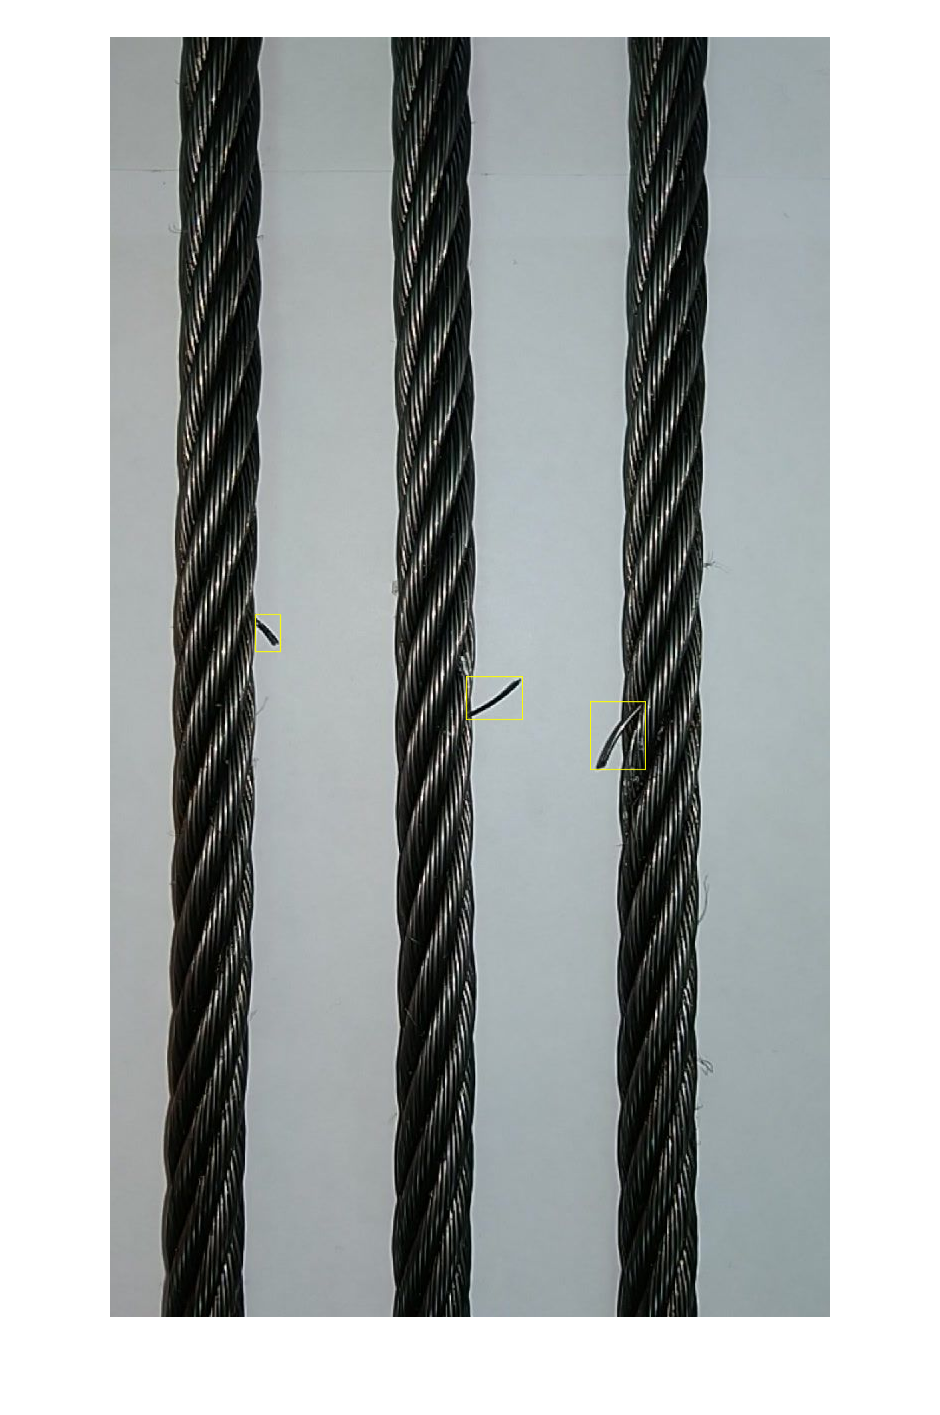

%-----------------------LOAD THE DATA SET-----------------------------------
%create a datastore
% imageFolder = fullfile('images\rope_defects\')
% imds1 = imageDatastore(imageFolder)

%preprocess images
% i = 1;
% while hasdata(imds1)
%     img = imread(imds1.Files{i})
%     imgr = rgb2gray(img)
%     save('images\rope_' + string(i) + '.jpg')
%     i = i+1;
% end

%Load the datastore:
% imageLabeler(imds1)

%load the rope ground truth data
data = load('models\labeled_wires.mat');
gTruth = data.gTruth;

% Add fullpath to the local rope data folder.
source = gTruth.DataSource.Source;

% Read one of the images.
I = imread(source{18});

% Insert the ROI labels.
I = insertShape(I, 'Rectangle', gTruth.LabelData.ROPE_WIRE{18});

% Resize and display image.
I = imresize(I,3);
figure
imshow(I)


%preraring training dataset
cds = objectDetectorTrainingData(gTruth)

cds = 71×2 table
                                                          imageFilename                                                            ROPE_WIRE  
    __________________________________________________________________________________________________________________________    ____________

    'C:\Users\Daria\YandexDisk\Дарья Яковлева\Work\ИКЦ Мысль\Проект LiftGuru-\src\matlab local\images\rope_defects\1-0508.jpg'    [2×4 double]
    'C:\Users\Daria\YandexDisk\Дарья Яковлева\Work\ИКЦ Мысль\Проект LiftGuru-\src\matlab local\images\rope_defects\1-1434.jpg'    [1×4 double]
    'C:\Users\Daria\YandexDisk\Дарья Яковлева\Work\ИКЦ Мысль\Проект LiftGuru-\src\matlab local\images\rope_defects\1-1660.jpg'    [1×4 double]
    'C:\Users\Daria\YandexDisk\Дарья Яковлева\Work\ИКЦ Мысль\Проект LiftGuru-\src\matlab local\images\rope_defects\1-2618.jpg'    [1×4 double]
    'C:\Users\Daria\YandexDisk\Дарья Яковлева\Work\ИКЦ М


%--------------DESIGN THE CONVOLUTIONAL NEURAL NETWORK (CNN)---------------

% Split data into a training and test set.
idx = floor(0.8 * height(cds));
trainingData = cds(1:idx,:);
testData = cds(idx:end,:); 

%create neural network
inputImageSize = [135 135 3];
% Create image input layer.
inputLayer = imageInputLayer(inputImageSize);


% Define the convolutional layer parameters.
filterSize = [5 5];
numFilters = 64;

% Create the middle layers.
middleLayers = [
                
    convolution2dLayer(filterSize, numFilters, 'Padding', 1)   
    reluLayer()
    convolution2dLayer(filterSize, numFilters, 'Padding', 1)  
    reluLayer() 
    maxPooling2dLayer(5,'Stride',3)    
    
    ];

finalLayers = [
    
    % Add a fully connected layer with 64 output neurons. The output size
    % of this layer will be an array with a length of 64.
    fullyConnectedLayer(120)

    % Add a ReLU non-linearity.
    reluLayer()

    % Add the last fully connected layer. At this point, the network must
    % produce outputs that can be used to measure whether the input image
    % belongs to one of the object classes or background. This measurement
    % is made using the subsequent loss layers.
    fullyConnectedLayer(width(cds))

    % Add the softmax loss layer and classification layer. 
    softmaxLayer()
    classificationLayer()
];

layers2 = [
    inputLayer
    middleLayers
    finalLayers
    ]

layers2 =   11x1 Layer array with layers:

     1   ''   Image Input             135x135x3 images with 'zerocenter' normalization
     2   ''   Convolution             64 5x5 convolutions with stride [1  1] and padding [1  1  1  1]
     3   ''   ReLU                    ReLU
     4   ''   Convolution             64 5x5 convolutions with stride [1  1] and padding [1  1  1  1]
     5   ''   ReLU                    ReLU
     6   ''   Max Pooling             5x5 max pooling with stride [3  3] and padding [0  0  0  0]
     7   ''   Fully Connected         120 fully connected layer
     8   ''   ReLU                    ReLU
     9   ''   Fully Connected         2 fully connected layer
    10   ''   Softmax                 softmax
    11   ''   Classification Output   crossentropyex


net = alexnet;
% layersTransfer = net.Layers(2:end-3);
% layers = [
%     imageInputLayer(inputImageSize);
%     layersTransfer
%     fullyConnectedLayer(width(cds))
%     softmaxLayer
%     classificationLayer];

% %number of objects to detect
% numClasses = 1; 
% %preprocessedTrainingData = transformSliderGainBlock(cds, @(data)preprocessData(data,inputSize));
% numAnchors = 3;
% %anchorBoxes = estimateAnchorBoxes(cds,numAnchors)
% % layers = [imageInputLayer(inputImageSize)
% %         convolution2dLayer([5 5],10)
% %         reluLayer()
% %         maxPooling2dLayer([3 3])
% %         fullyConnectedLayer(10)
% %         softmaxLayer()
% %         classificationLayer()];
% featureExtractionNetwork = resnet50;
% featureLayer = 'activation_40_relu';
% 
% lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

%-----------------------CONFIGURE TRAINING OPTIONS----------------------------------
% Options for step 1.
optionsStage1 = trainingOptions('sgdm', ...
    'MaxEpochs', 3, ...,
    'MiniBatchSize',1,...
    'InitialLearnRate', 1e-3, ...
    'CheckpointPath', tempdir);

% Options for step 2.
optionsStage2 = trainingOptions('sgdm', ...
    'MaxEpochs', 3, ...
    'MiniBatchSize',1,...
    'InitialLearnRate', 1e-3, ...
    'CheckpointPath', tempdir);

% Options for step 3.
optionsStage3 = trainingOptions('sgdm', ...
    'MaxEpochs', 3, ...
    'MiniBatchSize',1,...
    'InitialLearnRate', 1e-3, ...
    'CheckpointPath', tempdir);

% Options for step 4.
optionsStage4 = trainingOptions('sgdm', ...
    'MaxEpochs', 3, ...
    'MiniBatchSize',1,...
    'InitialLearnRate', 1e-3, ...
    'CheckpointPath', tempdir);

options = [
    optionsStage1
    optionsStage2
    optionsStage3
    optionsStage4
    ];



%  options = trainingOptions('sgdm', ... 
%       'MiniBatchSize', 1, ...
%       'InitialLearnRate', 1e-3, ...
%       'MaxEpochs', 7, ...
%       'VerboseFrequency', 200, ...
%       'CheckpointPath', tempdir);
  
%----------------------TRAIN FASTER R-CNN OBJECT DETECTOR------------------
% A trained network is loaded from disk to save time when running the
% example. Set this flag to true to train the network. 
doTrainingAndEval = true;

try
    nnet.internal.cnngpu.reluForward(1);
catch ME
end
% D = gpuDevice
% for ii = 1:gpuDeviceCount
%     D = gpuDevice(ii);
%     fprintf(1,'Device %i has ComputeCapability %s \n', ...
%             D.Index,D.ComputeCapability)
% end
if doTrainingAndEval
    % Set random seed to ensure example training reproducibility.
    rng(0);
    
    % Train Faster R-CNN detector. Select a BoxPyramidScale of 1.2 to allow
    % for finer resolution for multiscale object detection.
    detector = trainFasterRCNNObjectDetector(trainingData, net, options, ...
        'NegativeOverlapRange', [0 0.3], ...
        'PositiveOverlapRange', [0.6 1], ...
        'NumRegionsToSample', [256 128 256 128], ...
        'BoxPyramidScale', 1.2);
    time = string(datetime('now','Format','HH-mm-ss'))
    date = string(datetime('now','Format','dd-MMM-uuuu'))
else
    % Load pretrained detector for the example.
    model = load('models\detector_23-Apr-2021_13-34-15.mat')
    detector = model.detector;
end

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* ROPE_WIRE

Step 1 of 4: Training a Region Proposal Network (RPN).
Training on single GPU.
|=======================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|=======================================================================================================|
|       1 |           1 |       00:00:00 |       0.7529 |        3.13% |         1.03 |          0.0010 |
|       1 |          50 |       00:00:03 |       0.7365 |       96.48% |         1.05 |          0.0010 |
|       2 |         100 |       00:00:12 |       0.6877 |       95.31% |         0.86 |          0.0010 |
|       3 |      

Error using  * 
Call to sgemm in CUBLAS failed with error status: CUBLAS_STATUS_EXECUTION_FAILED.

Error in nnet.internal.cnn.layer.util.FullyConnectedImageStrategy/backwardConvolveOrMultiply (line 57)
                dX = reshape(this.sendToDevice(weights), [], szW(4)) * reshape(dZ, szW(4), []);

Error in 

%----------------------PREDICT DATA-----------------------------------------
% Read a test image.

    for i = 1:height(testData)
        
        % Read the image.
        I = imread(testData.imageFilename{i});
%         if (i == 3 || i == 4 || i == 6)
%             continue
%         end
        
        title('image for predict')
        
        % Run the detector.
        [bboxes, scores] = detect(detector, I);
        
       % Annotate detections in the image.
       if (isempty(bboxes))
           continue;
       end
        I = insertObjectAnnotation(I,'rectangle',bboxes, scores);
        figure
        imshow(I)
    end


%----------------------EVALUATE THE TRAINED DETECTOR---------------------
if doTrainingAndEval
    % Run detector on each image in the test set and collect results.
    resultsStruct = struct([]);
    for i = 1:height(testData)
        
        % Read the image.
        I = imread(testData.imageFilename{i});
        
        title('image for predict')
        imshow(I)
        
        % Run the detector.
        [bboxes, scores, labels] = detect(detector, I);
        
       
        % Collect the results.
        resultsStruct(i).Boxes = bboxes;
        resultsStruct(i).Scores = scores;
        resultsStruct(i).Labels = labels;
    end
    
    % Convert the results into a table.
    results = struct2table(resultsStruct);
    save('models\detector_' + date + '_' + time, 'detector','results')
else
    % Load results from disk.
    results = model.results;
end

% Extract expected bounding box locations from test data.
expectedResults = testData(:, 2:end);

% Evaluate the object detector using Average Precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults);

% Plot precision/recall curve
figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))
